# Word Recognition System

## TL;DR

This project presents a robust word recognition system developed for an Advanced DSP course, designed to classify audio inputs into three categories - **"Light on"**, **"Light off"**, **"Other"**.

**Dataset Overview -** The system was trained using 308 "Light on", 306 "Light off", and 602 "Other" audio samples. The testing phase utilized a balanced dataset consisting of 60 samples per category.

**System Logic -** The signal processing pipeline consists of three main stages - 

- **Pre-Processing -** Pre-Emphasis to boost high frequencies, Voice Activity Detection (VAD) to isolate the speech, and Hamming Windowing to divide the signal into short frames.

- **Feature Extraction - **The system extracts Mel-Frequency Cepstral Coefficients (MFCCs) along with their first and second derivatives, 39 features per frame.

- **Model Training -** These features are used to train Gaussian Mixture Models (GMM) which then classify new audio inputs based on maximum log-likelihood.

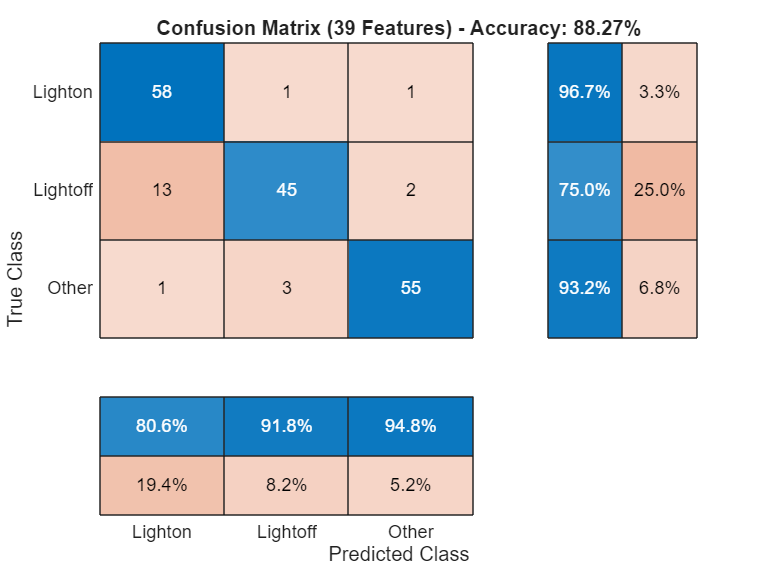

**Performance Evaluation -** The system achieved an overall accuracy of **88.27%**. The confusion matrix reveals strong classification rates for "Light on" (96.7%) and "Other" (93.2%), with "Light off" being slightly more challenging to classify (75.0% accuracy).

## Configuration

clc; clear; close all;

% Define paths
basePath = 'Data\Train';
pathOn = fullfile(basePath, 'LightOn');
pathOff = fullfile(basePath, 'LightOff');

% Get first wav file from each folder
filesOn = dir(fullfile(pathOn, '*.wav'));
filesOff = dir(fullfile(pathOff, '*.wav'));

% Read audio files
[audioOn, fsOn] = audioread(fullfile(pathOn, filesOn(1).name));
[audioOff, fsOff] = audioread(fullfile(pathOff, filesOff(1).name));

## Pre Emphasis

Pre-Emphasis applies a first-order high-pass filter (using `alpha = 0.97`) to the raw audio signal to amplify high frequencies, compensating for their natural attenuation in human speech and enhancing the accuracy of feature extraction.

% Time vectors
tOn = (0:length(audioOn)-1) / fsOn;
tOff = (0:length(audioOff)-1) / fsOff;

% Freq vectors
N_on = length(audioOn);
fOn = (0:N_on-1) * (fsOn / N_on);
half_N_on = floor(N_on/2);

N_off = length(audioOff);
fOff = (0:N_off-1) * (fsOff / N_off);
half_N_off = floor(N_off/2);

% Compute original FFT
fftOn_orig = abs(fft(audioOn));
fftOff_orig = abs(fft(audioOff));

% Apply pre-emphasis
alpha = 0.97;
preEmphOn = filter([1, -alpha], 1, audioOn);
preEmphOff = filter([1, -alpha], 1, audioOff);

% Compute pre-emphasized FFT
fftOn_pre = abs(fft(preEmphOn));
fftOff_pre = abs(fft(preEmphOff));

% Plot results
figure('Name', 'Pre-Emphasis Analysis', 'NumberTitle', 'off');
set(gcf, 'Units', 'centimeters', 'Position', [2, 2, 16, 12]);

% Time domain original
subplot(3,2,1); 
plot(tOn, audioOn); 
title('Light On Time Domain'); 
xlabel('Time (s)'); 
ylabel('Amp');

subplot(3,2,2); 
plot(tOff, audioOff); 
title('Light Off Time Domain'); 
xlabel('Time (s)'); 
ylabel('Amp');

% Freq domain original
subplot(3,2,3); 
plot(fOn(1:half_N_on), fftOn_orig(1:half_N_on)); 
title('Light On Freq Domain'); 
xlabel('Freq (Hz)'); 
ylabel('Mag');

subplot(3,2,4); 
plot(fOff(1:half_N_off), fftOff_orig(1:half_N_off)); 
title('Light Off Freq Domain'); 
xlabel('Freq (Hz)'); 
ylabel('Mag');

% Freq domain pre-emphasized
subplot(3,2,5); 
plot(fOn(1:half_N_on), fftOn_pre(1:half_N_on)); 
title('Light On Freqency after Pre-Emphasis'); 
xlabel('Freq (Hz)'); 
ylabel('Mag');

subplot(3,2,6); 
plot(fOff(1:half_N_off), fftOff_pre(1:half_N_off)); 
title('Light Off Freqency after Pre-Emphasis'); 
xlabel('Freq (Hz)'); 
ylabel('Mag');

By comparing the Original FFT vs the Pre-Emphasized FFT in the plots above, we can clearly see that the higher frequency components are now more prominent, providing a more balanced representation of the speech signal.

## VAD

After pre-emphasis, we implement Voice Activity Detection (VAD) to isolate the actual speech segments from the background environment.

The primary objective of this stage is to isolate the speech signal by removing periods of silence and ambient noise from the recordings. By implementing this Voice Activity Detection (VAD), we ensure that the subsequent feature extraction stage (MFCC) processes only relevant acoustic data. This prevents the model from capturing "noise features," thereby maintaining high signal integrity and improving the overall accuracy of the word recognition system.

% Define window length for energy envelope 
winLenOn = round(0.02 * fsOn);
winLenOff = round(0.02 * fsOff);

% Calculate signal envelope using moving average
envOn = movmean(abs(preEmphOn), winLenOn);
envOff = movmean(abs(preEmphOff), winLenOff);

% Define threshold for VAD 
threshOn = 0.1 * max(envOn);
threshOff = 0.1 * max(envOff);

% Create VAD mask
vadMaskOn = envOn > threshOn;
vadMaskOff = envOff > threshOff;

% Apply VAD mask to keep only active speech
vadSignalOn = preEmphOn(vadMaskOn);
vadSignalOff = preEmphOff(vadMaskOff);

% Create time vectors for VAD signals
tVadOn = (0:length(vadSignalOn)-1) / fsOn;
tVadOff = (0:length(vadSignalOff)-1) / fsOff;

% Plot results
figure('Name', 'VAD Analysis', 'NumberTitle', 'off');
set(gcf, 'Units', 'centimeters', 'Position', [2, 2, 16, 12]);

% Time domain pre-emphasized
subplot(3,2,1);
plot(tOn, preEmphOn);
title('Light On: Time');
xlabel('Time (s)');
ylabel('Amp');

subplot(3,2,2);
plot(tOff, preEmphOff);
title('Light Off: Time');
xlabel('Time (s)');
ylabel('Amp');

% VAD mask
subplot(3,2,3);
plot(tOn, vadMaskOn, 'r', 'LineWidth', 1.5);
ylim([-0.2, 1.2]);
title('Light On: VAD Mask');
xlabel('Time (s)');
ylabel('Logic');

subplot(3,2,4);
plot(tOff, vadMaskOff, 'r', 'LineWidth', 1.5);
ylim([-0.2, 1.2]);
title('Light Off: VAD Mask');
xlabel('Time (s)');
ylabel('Logic');

% Signal after VAD
subplot(3,2,5);
plot(tVadOn, vadSignalOn);
title('Light On: After VAD');
xlabel('Time (s)');
ylabel('Amp');

subplot(3,2,6);
plot(tVadOff, vadSignalOff);
title('Light Off: After VAD');
xlabel('Time (s)');
ylabel('Amp');

## Windowing 

Because speech is a non-stationary signal, it is analyzed in short, overlapping frames of about 25 ms each.

The problem is that abrupt segmentation of the signal introduces spectral leakage, caused by sharp discontinuities at the frame boundaries.

To address this, a Hamming window is applied to every frame. The window gradually attenuates the signal toward the edges, reducing discontinuities and providing a more reliable frequency representation during the FFT stage.

% Define frame parameters 
frameDuration = 0.025; 
winLenOn = round(frameDuration * fsOn);
winLenOff = round(frameDuration * fsOff);

% Create Hamming window
hamWinOn = hamming(winLenOn);
hamWinOff = hamming(winLenOff);

% Extract a single frame from the middle of the signals
midIdxOn = round(length(vadSignalOn) / 2);
frameOrigOn = vadSignalOn(midIdxOn : midIdxOn + winLenOn - 1);

midIdxOff = round(length(vadSignalOff) / 2);
frameOrigOff = vadSignalOff(midIdxOff : midIdxOff + winLenOff - 1);

% Apply window to the frames
frameWinOn = frameOrigOn .* hamWinOn;
frameWinOff = frameOrigOff .* hamWinOff;

% Time vectors for a single frame
tFrameOn = (0:winLenOn-1) / fsOn;
tFrameOff = (0:winLenOff-1) / fsOff;

% Plot results
figure('Name', 'Windowing Analysis', 'NumberTitle', 'off');
set(gcf, 'Units', 'centimeters', 'Position', [2, 2, 16, 12]);

% Signal after VAD
subplot(3,2,1);
plot(tVadOn, vadSignalOn);
title('Light On: After VAD');
xlabel('Time (s)');
ylabel('Amp');

subplot(3,2,2);
plot(tVadOff, vadSignalOff);
title('Light Off: After VAD');
xlabel('Time (s)');
ylabel('Amp');

% Hamming Window
subplot(3,2,3);
plot(tFrameOn, hamWinOn, 'LineWidth', 1.5);
title('Hamming Window (25ms)');
xlabel('Time (s)');
ylabel('Amp');

subplot(3,2,4);
plot(tFrameOff, hamWinOff, 'LineWidth', 1.5);
title('Hamming Window (25ms)');
xlabel('Time (s)');
ylabel('Amp');

% Frame after Windowing
subplot(3,2,5);
plot(tFrameOn, frameOrigOn, '--', 'Color', [0.5 0.5 0.5]); 
hold on;
plot(tFrameOn, frameWinOn, 'b', 'LineWidth', 1.2);
hold off;
title('Light On: Windowed Frame');
xlabel('Time (s)');
ylabel('Amp');

subplot(3,2,6);
plot(tFrameOff, frameOrigOff, '--', 'Color', [0.5 0.5 0.5]); 
hold on;
plot(tFrameOff, frameWinOff, 'b', 'LineWidth', 1.2);
hold off;
title('Light Off: Windowed Frame');
xlabel('Time (s)');
ylabel('Amp');

## Feature Extraction & MFCC

To represent voice commands mathematically, we extract Mel-Frequency Cepstral Coefficients (MFCCs). The speech signal is divided into short frames (20–40 ms), windowed with a Hamming function, and transformed to the frequency domain using the STFT. The spectrum is passed through a Mel-scale filterbank, followed by logarithmic scaling and a DCT to obtain the coefficients. Typically, the first 13 MFCCs are retained to describe the vocal tract characteristics. In our implementation, we expand them to 39 features by adding Delta and Delta-Delta coefficients to capture speech dynamics over time.

% Define parameters
winLenOn = round(0.025 * fsOn);
overlapOn = round(0.015 * fsOn);
winLenOff = round(0.025 * fsOff);
overlapOff = round(0.015 * fsOff);

% Create windows
windowOn = hamming(winLenOn);
windowOff = hamming(winLenOff);

% Create figure
figure('Name', 'Spectrogram and MFCC', 'NumberTitle', 'off');
set(gcf, 'Units', 'centimeters', 'Position', [2, 2, 16, 12]);

% Calculate Spectrogram On
subplot(2,2,1);
spectrogram(vadSignalOn, windowOn, overlapOn, 1024, fsOn, 'yaxis');
title('Light On Spectrogram');

% Calculate Spectrogram Off
subplot(2,2,2);
spectrogram(vadSignalOff, windowOff, overlapOff, 1024, fsOff, 'yaxis');
title('Light Off Spectrogram');

% Extract MFCC features
[coeffsOn, ~, ~, ~] = mfcc(vadSignalOn, fsOn, 'Window', windowOn, 'OverlapLength', overlapOn);
[coeffsOff, ~, ~, ~] = mfcc(vadSignalOff, fsOff, 'Window', windowOff, 'OverlapLength', overlapOff);

% Plot MFCC Heat Map On
subplot(2,2,3);
imagesc(coeffsOn');
axis xy;
title('Light On MFCC');
xlabel('Frames');
ylabel('Coefficients');
colorbar;

% Plot MFCC Heat Map Off
subplot(2,2,4);
imagesc(coeffsOff');
axis xy;
title('Light Off MFCC');
xlabel('Frames');
ylabel('Coefficients');
colorbar;

## GMM Traning

The system trains three separate Gaussian Mixture Models (each with 16 mixtures) to statistically represent the 39-dimensional feature distribution for 'Light on', 'Light off', and 'Other' categories. The trained models are saved as a `.mat` file for real-time classification and deployment

% Define paths
trainBase = 'Data\Train';
categories = {'Lighton', 'Lightoff', 'Other'};
numCategories = length(categories);

% Update GMM parameters
numMixtures = 16; 
options = statset('MaxIter', 200, 'Display', 'final');

% Preallocate
allFeatures = cell(1, numCategories);

for c = 1:numCategories
    folderPath = fullfile(trainBase, categories{c});
    files = dir(fullfile(folderPath, '*.wav'));
    currFeatures = [];
    
    for f = 1:length(files)
        [audio, fs] = audioread(fullfile(folderPath, files(f).name));
        
        % Pre-Emphasis
        audio = filter([1, -0.97], 1, audio);
        
        % VAD
        winLen = round(0.02 * fs);
        env = movmean(abs(audio), winLen);
        thresh = 0.1 * max(env);
        vadSignal = audio(env > thresh);
        
        % Define MFCC window length
        winLenMfcc = round(0.025 * fs);
        
        % Check if valid length for MFCC
        if isempty(vadSignal) || length(vadSignal) < winLenMfcc
            continue;
        end
        
        % Extract MFCC and derivatives
        overlapMfcc = round(0.015 * fs);
        window = hamming(winLenMfcc);
        [coeffs, delta, deltaDelta, ~] = mfcc(vadSignal, fs, 'Window', window, 'OverlapLength', overlapMfcc);
        
        % Concatenate to 39 dimensions
        features = [coeffs, delta, deltaDelta];
        
        % Append
        currFeatures = [currFeatures; features];
    end
    
    allFeatures{c} = currFeatures;
end

% Train
gmmOn = fitgmdist(allFeatures{1}, numMixtures, 'Options', options, 'RegularizationValue', 0.01);
gmmOff = fitgmdist(allFeatures{2}, numMixtures, 'Options', options, 'RegularizationValue', 0.01);
gmmOther = fitgmdist(allFeatures{3}, numMixtures, 'Options', options, 'RegularizationValue', 0.01);

disp('GMM Training Completed Successfully.');
% Save the models to a .mat file
savePath = 'models\trained_gmm_models.mat';
save(savePath, 'gmmOn', 'gmmOff', 'gmmOther');
disp(['Models saved successfully to: ', savePath]);

## Test

During the testing phase, the system processes unseen audio samples through the same pipeline and calculates the log-likelihood for each of the three trained GMM models. The sample is classified based on the maximum score , and the final performance is evaluated using a confusion matrix to visualize precision 

% Define test paths
testBase = 'Data\Test';
categories = {'Lighton', 'Lightoff', 'Other'};
numCategories = length(categories);

% Initialize arrays
trueLabels = [];
predLabels = [];

for c = 1:numCategories
    folderPath = fullfile(testBase, categories{c});
    files = dir(fullfile(folderPath, '*.wav'));
    
    for f = 1:length(files)
        [audio, fs] = audioread(fullfile(folderPath, files(f).name));
        
        % Pre-Emphasis
        audio = filter([1, -0.97], 1, audio);
        
        % VAD
        winLen = round(0.02 * fs);
        env = movmean(abs(audio), winLen);
        thresh = 0.1 * max(env);
        vadSignal = audio(env > thresh);
        
        winLenMfcc = round(0.025 * fs);
        
        % Check length
        if isempty(vadSignal) || length(vadSignal) < winLenMfcc
            continue;
        end
        
        % Extract MFCC and derivatives
        overlapMfcc = round(0.015 * fs);
        window = hamming(winLenMfcc);
        [coeffs, delta, deltaDelta, ~] = mfcc(vadSignal, fs, 'Window', window, 'OverlapLength', overlapMfcc);
        
        % Concatenate to 39 dimensions
        features = [coeffs, delta, deltaDelta];
        
        % Calculate log-likelihood
        scoreOn = sum(log(pdf(gmmOn, features) + 1e-10));
        scoreOff = sum(log(pdf(gmmOff, features) + 1e-10));
        scoreOther = sum(log(pdf(gmmOther, features) + 1e-10));
        
        % Find max score
        [~, predIdx] = max([scoreOn, scoreOff, scoreOther]);
        
        % Store labels
        trueLabels = [trueLabels; c];
        predLabels = [predLabels; predIdx];
    end
end

% Calculate accuracy
accuracy = sum(trueLabels == predLabels) / length(trueLabels) * 100;
fprintf('Overall System Accuracy (39 Features): %.2f%%\n', accuracy);
% Categorical arrays
trueCat = categorical(trueLabels, 1:3, categories);
predCat = categorical(predLabels, 1:3, categories);

% Plot Confusion Matrix
figure('Name', 'System Evaluation (39 Features)', 'NumberTitle', 'off');
set(gcf, 'Units', 'centimeters', 'Position', [2, 2, 16, 12]);

cm = confusionchart(trueCat, predCat);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
title(sprintf('Confusion Matrix (39 Features) - Accuracy: %.2f%%', accuracy));